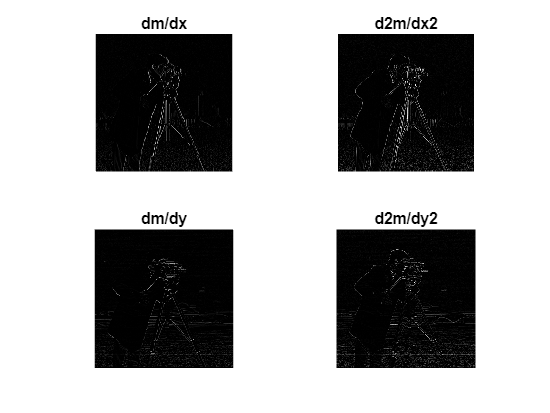

x=imread("cameraman.tif");
x=im2double(x);
n=size(x,1);


M_x=x(:,[2:end])-x(:,[1:end-1]);
M_xx=M_x(:,[2:end])-M_x(:,[1:end-1]);
M_2x=x(:,[1:end-2])-2*x(:,[2:end-1])+x(:,[3:end]);
subplot(2,2,1)
imshow(M_x)
title("dm/dx")
subplot(2,2,2)
imshow(M_xx)
title("d2m/dx2")


M_y=x([2:end],:)-x([1:end-1],:);
M_yy=M_y([2:end],:)-M_y([1:end-1],:);
M_2y=x([1:end-2],:)-2*x([2:end-1],:)+x([3:end],:);
subplot(2,2,3)
imshow(M_y)
title("dm/dy")
subplot(2,2,4)
imshow(M_yy)
title("d2m/dy2")